# Perform Parameter Sensitivity Analysis for Robot Work Envelope

This example shows how to perform parameter sensitivity analysis for a work envelope of a 6-axis articulated robot.

Copyright 2023 - 2024 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('RobotDesignOverview.html')).

## Parameter Sensitivity Analysis

You can use parameter sensitivity analysis to study how the performance of a system depends on key design parameters. Reasons to do this include:

- To identify the design parameters that have significant impact on the model behavior.

- To determine if the system displays the expected dependency on input parameters.

- To determine the permissible working range for key design parameters while still delivering  the required system behavior and/or performance.

- To identify if there are common sets of design parameters that influence system behavior in a similar way.

- To determine requisite manufacturing tolerances to ensure system performance requirements are always met.

To perform the analysis, this example uses Sensitivity Analyzer APIs from the Simulink Design Optimization toolbox. 

## Create Early Stage Design Using Simscape Multibody™

Traditional mechanical design of a robot involves creating a CAD file first. You use this file to build a prototype and test the established functional requirements. If the requirements are not met, re-generate the CAD file and the process continues over multiple iterations. This iterative design approach can be time-consuming and computationally expensive. Instead, using Simscape Multibody™ enables you to check if the robot meets the requirements and is beneficial in system level mechanical design or early stage design.

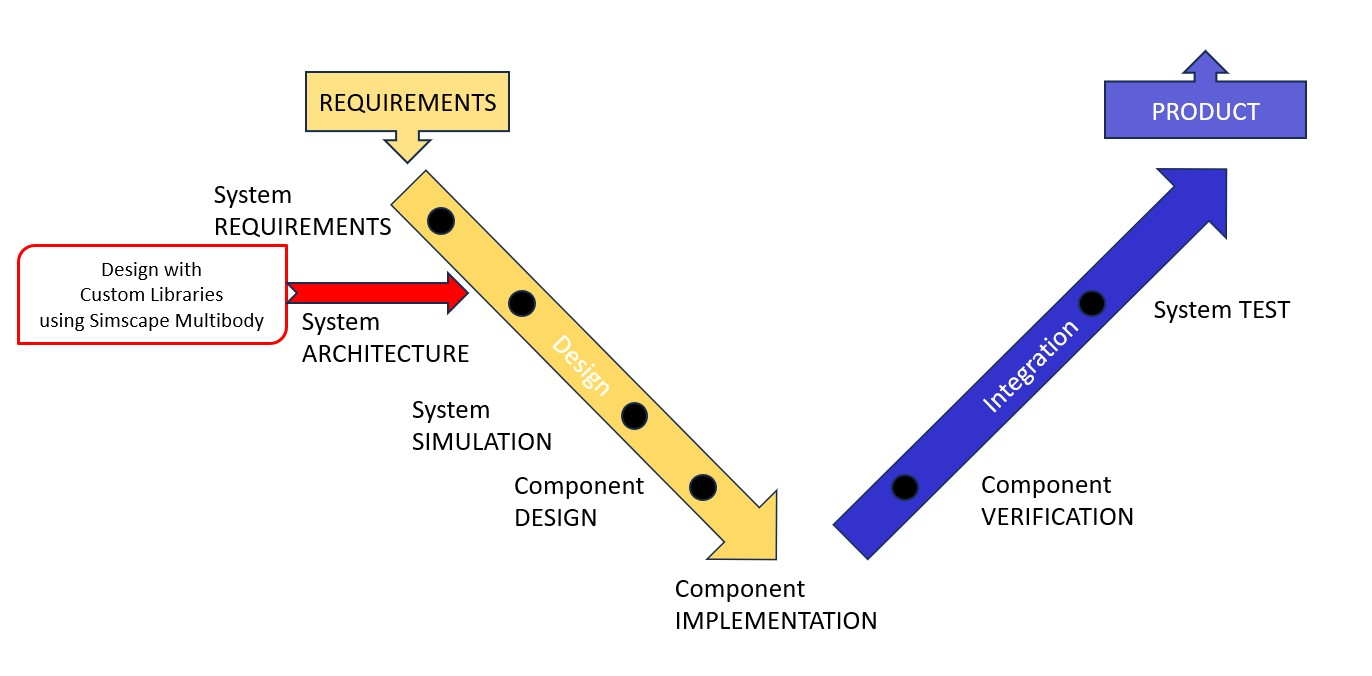

This example shows the application of custom libraries using Simscape Multibody. These custom libraries contain elementary building blocks like [Link](matlab:open('../../Component/html/Link.html')), [L-Link](matlab:open('../../Component/html/LLink.html')), [Rotating Base with Bracket](matlab:open('../../Component/html/RotatingBaseWithBracket.html')), [Two Finger Gripper](matlab:open('../../Component/html/TwoFingerGripper.html')) which enable you to create system level design or early stage design. You can build your own robot model using the custom blocks and simulate the model for defined design parameters and working conditions. You can view and interpret the simulation results and vary the design parameters to meet the functional requirements. This process eliminates the need to build a CAD file and prototype to finalize an early stage design. This method is complementary to the process of generation of a CAD file and does not attempt to replace it.

### Select Robot

This example uses a 6-axis or 6-DOF parametric robot that represents a typical industrial articulated robot.

You can build the robot model using Simscape Multibody custom libraries. The model has one base with a coupled rotor and five links connected to each other using revolute joints. To learn about the model setup using Simscape Multibody, see [Robot Model Setup](matlab:open('../../Component/MultibodyModelSetup/html/RobotModelSetupHelp.html')). To load the parameters, run the input script.

inputScript = 'ParametricRobotParameters';
run(inputScript);

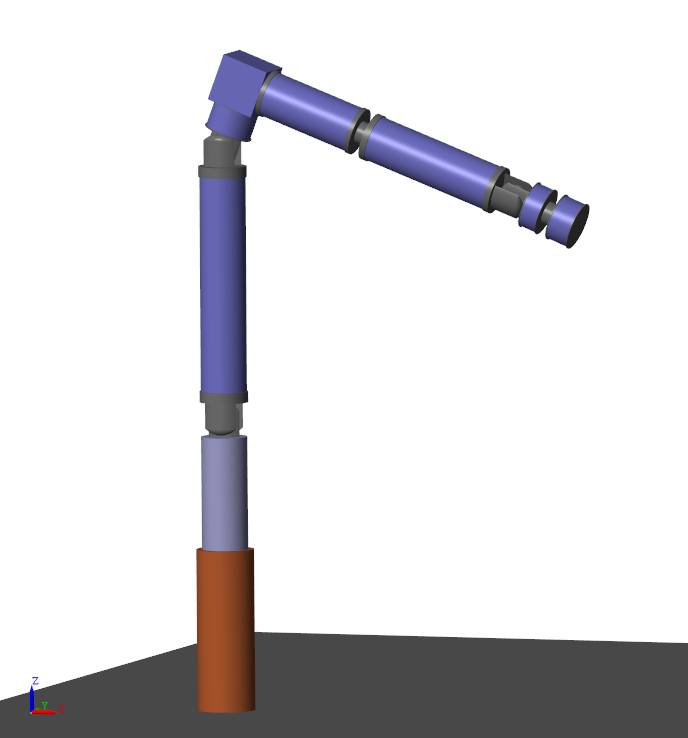

### Define Work Envelope Performance Metrics

The work envelope of a robot is a critical aspect because it defines the space in which the robot can operate. You can quantify the work envelope using two types of reach: vertical reach and horizontal reach. Vertical reach determines the maximum height a robot arm can obtain when extended upward from its base. Horizontal reach defines the maximum distance obtained from the center of the robot base to its wrist. The unreachable area of a robot is the space that the robot cannot reach. 

Horizontal reach and unreachable area are two key performance metrics that define the horizontal work envelope of an articulated robot. Horizontal reach of an articulated robot depends on the individual link lengths, joint configurations, and joint angular position limits. This example shows the effect of variation of link lengths on horizontal reach, while keeping the joint configurations and angular position limits constant.

Work envelope determination is an essential step to perform parameter sensitivity analysis and to evaluate joint actuator ratings. To determine the work envelope of the robot for a given architecture, see [Determine Work Envelope of Robot Arm](matlab:open('../ActuatorRating/DetermineEnvelopeWorkflow.mlx')).

### Identify Design Parameters

This example demonstrates the impact of the following design parameters on horizontal reach and the unreachable area of the robot:

- `baseLength`

- `link1Length`

- `link2VerticalLength`

- `link2HorizontalLength`

- `link3Length`

- `link4Length`

- `link5Length`

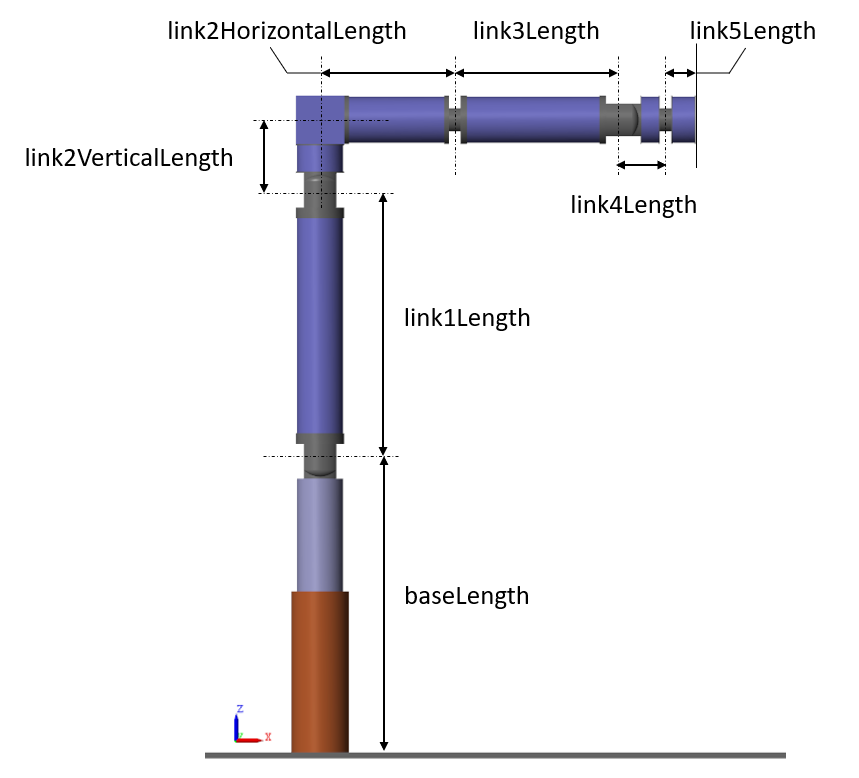

## Setup and Run Parameter Sensitivity Analysis

Setup the experiment for parameter sensitivity analysis using Simulink Design Optimization toolbox. This involves the following steps.

- **Determine the range and distribution of the parameters:** The parameter variation of an assembled part is a function of the manufacturing tolerances achieved. For example, the variation in the length of the robot arm link can account for the manufacturing tolerances. This example assumes 10% design parameter variation that follows a normal distribution with 3-sigma rule. 

- **Sample the parameter space:** This step shows how to generate 500 parameter combinations that span the parameter space. You can use a higher number of samples for higher confidence.

- **Define system performance metric: **This step defines a requirements function that returns a metric of system performance. The goal is to identify the design parameters that have significant impact on the requirements function and system performance. Because this example studies the horizontal work envelope, choose the horizontal reach and the unreachable radius of the robot as the system performance metrics.

- **Setup the objective function: **This step shows how to create a custom objective function. The objective function computes the horizontal reach and the unreachable radius of the robot for the generated parameter space.

To learn more about the details of the setup and edit the setup to meet requirements, see [Parameter Sensitivity Analysis Setup](matlab:open('./ParameterSensitivityAnalysisSetup.mlx')).

Once setup is complete, run the parameter sensitivity analysis.

parameterSample = 500×7 table
     BaseL     Link1L     Link2VL     Link2HL    Link3L      Link4L      Link5L 
    _______    _______    ________    _______    _______    ________    ________

     0.2926    0.26964    0.070786    0.13024    0.16883    0.041362    0.030435
    0.29886    0.27404    0.069219    0.13492    0.17136    0.042035    0.030165
    0.27908    0.27083    0.069533    0.13512    0.17105    0.042755    0.029326
    0.29417    0.27131    0.069216    0.13419      0.167    0.042216    0.030774
    0.29154    0.27051    0.070672    0.13435    0.16764     0.04221    0.029692
    0.28368    0.27198    0.069092    0.13282    0.17005    0.041862    0.029651
     0.2879    0.27046    0.068759    0.13561    0.16834    0.041898    0.029288
  

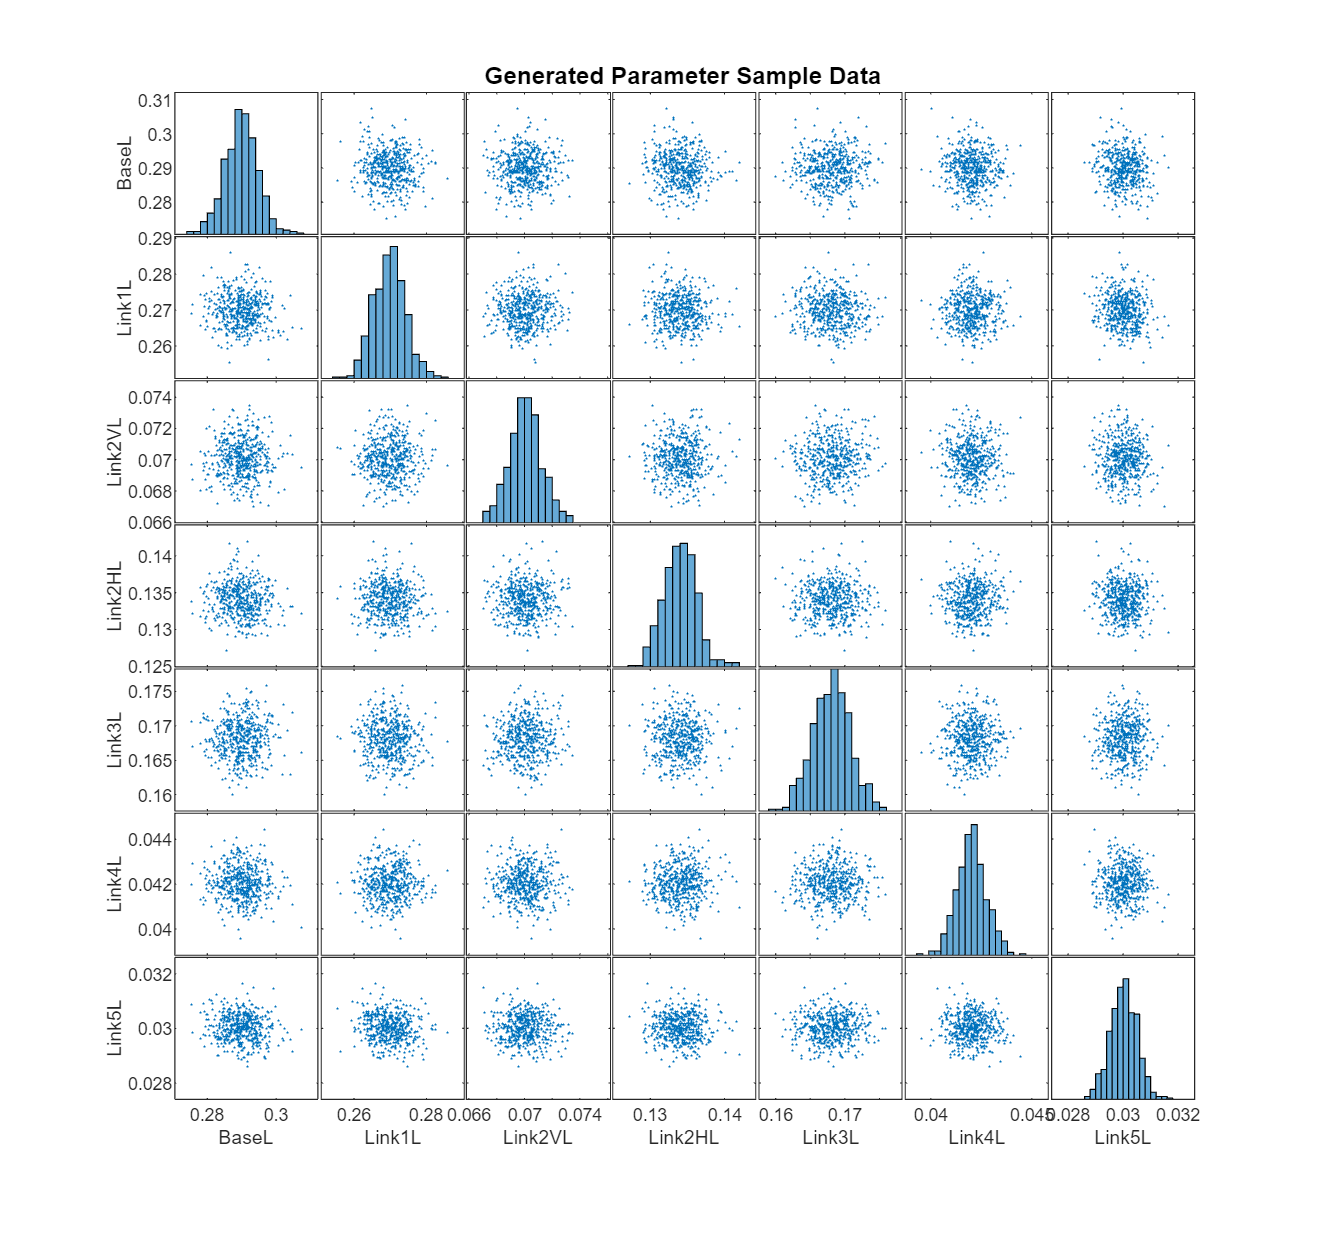

run ParameterSensitivityAnalysisSetup

## Analyze Results

### Evaluate the Experiment Setup

Now that you have setup the experiment, you can evaluate the results.

results = sdo.evaluate(estimationFcn, parameterSpace, parameterSample);

Model evaluated at 500 samples.


### Plot Results

Plot the scatter plot of objectives versus each parameter under consideration.

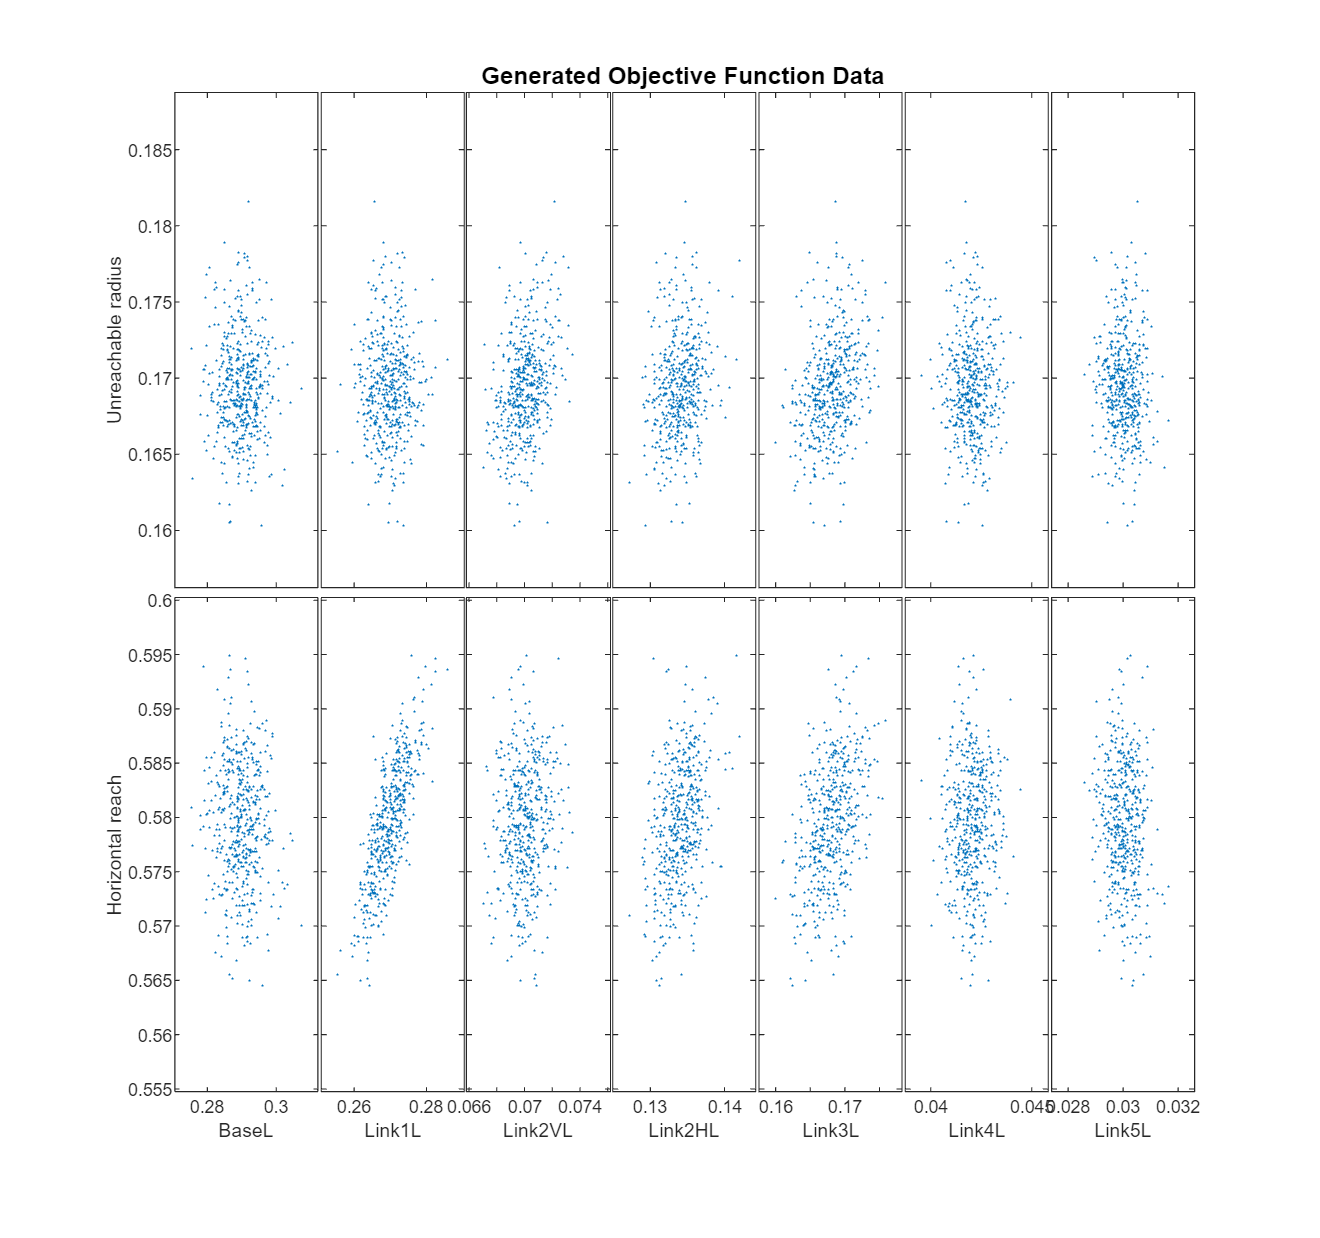

scatterPlotErrorFigH = figure;
set(scatterPlotErrorFigH,'Position',[800 200 800 750])
[H,AX,BigAX,P,PAx] = sdo.scatterPlot(parameterSample,results);
title('Generated Objective Function Data');
ylabel(AX(1),'Unreachable radius');
ylabel(AX(2),'Horizontal reach');

Also, plot the sensitivity of each parameter using the Ranked Standardized regression method. 

opts = sdo.AnalyzeOptions;
opts.Method = {'StandardizedRegression'}; % Other options:'Correlation','PartialCorrelation', 'All'
opts.MethodOptions = {'Ranked'}; % Other option: 'Linear', 'Kendall', 'AllApplicable'
sensitivities = sdo.analyze(parameterSample, results, opts);
sensitivities.Properties.VariableNames(1) = {'Unreachable radius'};
sensitivities.Properties.VariableNames(2) = {'Horizontal reach'};
save('sensitivities.mat','sensitivities')
disp(sensitivities);

               Unreachable radius    Horizontal reach
               __________________    ________________

    BaseL         -0.00055199             0.011897   
    Link1L           0.049648              0.80184   
    Link2VL            0.3088             0.057992   
    Link2HL           0.20819              0.37301   
    Link3L            0.32543              0.48195   
    Link4L         -0.0066289             0.020295   
    Link5L           -0.04938           -0.0048452   



A higher sensitivity value indicates that the design is dependent on the corresponding parameters. A positive sign for the sensitivity indicates the objective function is directly proportional to the parameters under consideration, while a negative sign indicates that the objective function is inversely proportional to the respective parameter.

A Tornado plot gives a graphical representation of sensitivities of parameters for each objective function. In this case there are two objective functions, so there are two subplots in the Tornado plot.

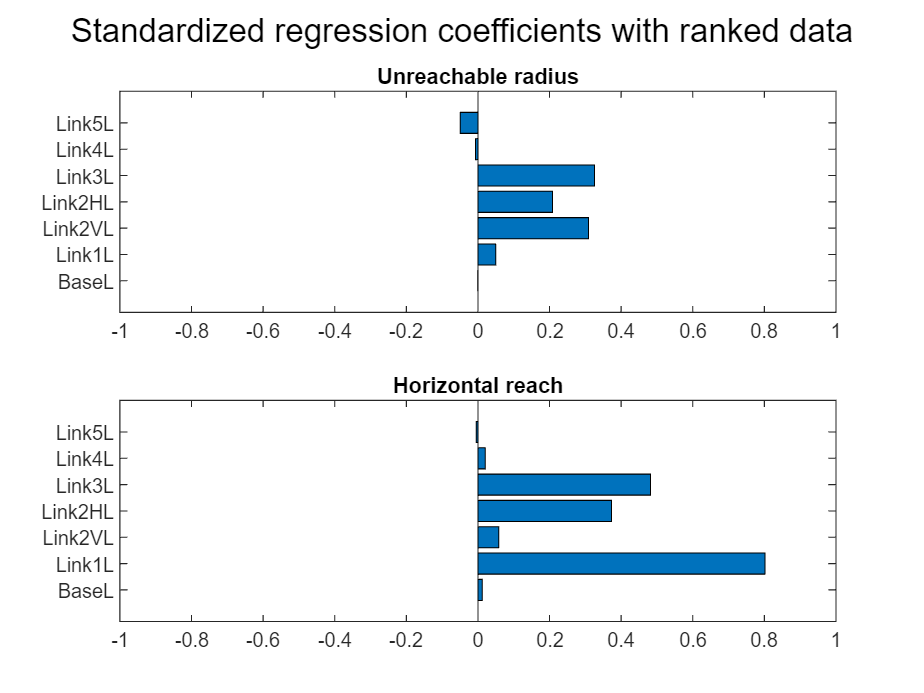

tornadoPlotFigH = parametricRobotSensitivityTornadoPlot(sensitivities);

## Conclusion

From the above table and the tornado plot, you can infer that the horizontal reach is highly dependent on Link 1 length, Link 3 length and Link 2 horizontal length, in order of decreasing significance. Link 2 vertical length impacts horizontal reach by a small amount. Increases in four of these design parameters leads to an increase in the reach. Base length, Link 4 length and Link 5 length have insignificant impact on the horizontal reach. 

Unreachable radius is highly dependent on Link 3 length, Link 2 vertical length, Link 2 horizontal length and Link 1 length, in order of decreasing significance. A decrease in the above four design parameters leads to a decrease in the unreachable radius. Base length, Link 4 length and Link 5 length have insignificant impact on unreachable radius.

These results are expected as an increase in length of the longer links (Link 1, Link 2 horizontal member and Link 3) should increase the reach. Also, the base length should not impact the horizontal reach, as the base only rotates around the vertical axis.